# Plotter

Ce fichier .mlx permet de plotter les données obtenues lors des essais

## Trajectoires

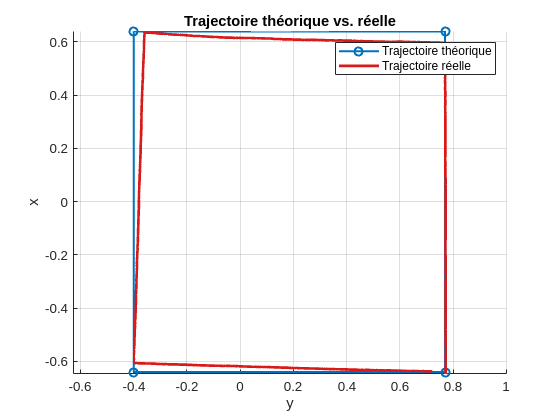

clear all
warning('off', 'all');



% === Tracé ===
figure;
hold on;
grid on;
axis equal;

% Lire les lignes du fichier
filename = '~/mecanum/csv/distributed_barycenter_logger.csv';
lines = readlines(filename);

% Extraire le type de trajectoire depuis la première ligne
trajectory_type_line = lines(1);
trajectory_type = strtrim(extractAfter(trajectory_type_line, 'trajectory_type:'));

% Lire les données de trajectoire (en ignorant les 2 premières lignes)
data = readtable(filename);

if strcmpi(trajectory_type, 'eight')
    % === Trajectoire théorique ===
    a = 1.0;
    b = 0.23;
    num_points = 16;
    start_x = -0.64;
    start_y = -0.77;
    
    X = zeros(num_points + 2, 1);
    Y = zeros(num_points + 2, 1);
    
    X(1) = start_x;
    Y(1) = start_y;
    
    for i = 1:num_points-1
        t = 2 * pi * (i-1) / num_points;
        X(i+1) = a * sin(t);
        Y(i+1) = b * sin(2 * t);
    end
    
    X(end) = start_x;
    Y(end) = start_y;
    % Trajectoire théorique (points cibles)
    plot(-Y, X, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Trajectoire théorique');
    % Numérotation des points
    for i = 1:length(X)
        text(-Y(i)+0.01, X(i)+0.01, num2str(i-1), 'FontSize', 8);
    end
    hold on
elseif strcmpi(trajectory_type, 'rectangle')
    vertices = [
        -0.64, -0.77;
         0.64, -0.77;
         0.64,  0.4;
        -0.64,  0.4;
        -0.64, -0.77;
    ];
    plot(-vertices(:,2), vertices(:,1), '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Trajectoire théorique');
    hold on
end

% === Trajectoire réelle depuis CSV ===


% Extraire x et y
x_real = data.x;
y_real = data.y;

% Trajectoire réelle (essaim)
plot(-y_real, x_real, '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 2, 'DisplayName', 'Trajectoire réelle');

xlabel('y');
ylabel('x');
title('Trajectoire théorique vs. réelle');
legend;

## Distances

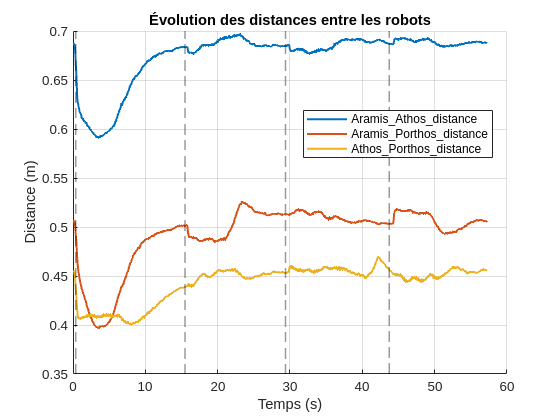

warning('off', 'all');

% === Paramètres ===
fichier_distance = '~/mecanum/csv/distributed_distance_logger.csv';   % CSV des distances
fichier_trajectoire = '~/mecanum/csv/distributed_goal_point_logger.csv';    % CSV des timestamps de position

% === Lecture du fichier des distances ===
data = readtable(fichier_distance);
timestamps_absolute = datetime(data{:, 1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
timestamps = seconds(timestamps_absolute - timestamps_absolute(1));  % temps relatif en secondes

% === Lecture du fichier de trajectoire ===
trajectoire = readtable(fichier_trajectoire);
timestamps_points_absolute = datetime(trajectoire{:, 1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
timestamps_points = seconds(timestamps_points_absolute - timestamps_absolute(1));  % même base temporelle

% === Tracé des distances ===
figure;
hold on;
grid on;

% Tracer chaque courbe de distance
for i = 2:width(data)
    nom_distance = data.Properties.VariableNames{i};
    valeurs = data{:, i};
    
    plot(timestamps, valeurs, 'DisplayName', strrep(nom_distance, '_', '\_'), 'LineWidth', 1.5);
end

% === Ajout des lignes verticales pour chaque point de trajectoire ===
yl = ylim;  % Limites verticales du graphe
for i = 2:length(timestamps_points)
    xline(timestamps_points(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

xlabel('Temps (s)');
ylabel('Distance (m)');
title('Évolution des distances entre les robots');
legend('Location', 'best');

## Commandes

% Dossier contenant les CSV
folder = '~/mecanum/csv';
files = dir(fullfile(folder, '*_cmd_vel_rate.csv'));

robot_names = {};
timestamp_counts = [];
timestamp_data = containers.Map;
dt_stats = containers.Map;

% Lecture des fichiers
for i = 1:length(files)
    filename = fullfile(folder, files(i).name);
    data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');
    
    % Conversion des timestamps
    timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

    % Nom du robot
    robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
    robot_names{end+1} = robot_name;

    % Temps relatif (temps 0 = premier timestamp)
    timestamps_rel = seconds(timestamps - timestamps(1));
    timestamp_data(robot_name) = timestamps_rel;
    timestamp_counts(end+1) = numel(timestamps_rel);

    % Étude statistique du delta t
    delta_t = seconds(diff(timestamps));
    stats.mean = mean(delta_t);
    stats.std = std(delta_t);
    stats.min = min(delta_t);
    stats.max = max(delta_t);
    dt_stats(robot_name) = stats;

    % Affichage console
    fprintf('\nRobot: %s\n', robot_name);
    fprintf('  N = %d commandes\n', numel(timestamps));
    fprintf('  Δt moyen    : %.4f s\n', stats.mean);
    fprintf('  Δt min      : %.4f s\n', stats.min);
    fprintf('  Δt max      : %.4f s\n', stats.max);
    fprintf('  Δt std dev  : %.4f s\n', stats.std);
end


Robot: Aramis


  N = 568 commandes


  Δt moyen    : 0.1003 s


  Δt min      : 0.0001 s


  Δt max      : 1.2969 s


  Δt std dev  : 0.1099 s



Robot: Athos


  N = 565 commandes


  Δt moyen    : 0.1009 s


  Δt min      : 0.0001 s


  Δt max      : 1.6243 s


  Δt std dev  : 0.1178 s



Robot: Porthos


  N = 571 commandes


  Δt moyen    : 0.0998 s


  Δt min      : 0.0001 s


  Δt max      : 2.1124 s


  Δt std dev  : 0.1240 s


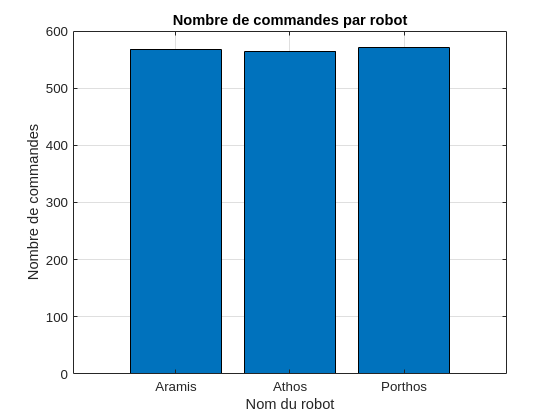


%% Figure 1 : Histogramme (bar chart)
figure;
bar(categorical(robot_names), timestamp_counts);
xlabel('Nom du robot');
ylabel('Nombre de commandes');
title('Nombre de commandes par robot');
grid on;

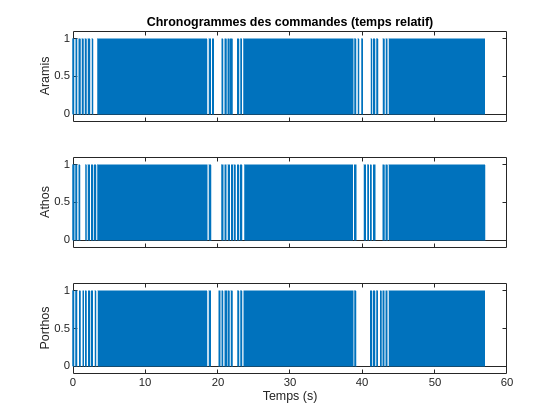


%% Figure 2 : Chronogramme (subplots synchronisés)
figure;
n = length(robot_names);

% Fusionner tous les temps relatifs uniques
all_times = [];
for i = 1:n
    all_times = [all_times; timestamp_data(robot_names{i})];
end
all_times = unique(all_times);

% Chronogrammes synchronisés
for i = 1:n
    ax = subplot(n,1,i);
    timestamps = timestamp_data(robot_names{i});
    y = ismember(all_times, timestamps);
    stem(all_times, y, 'Marker', 'none', 'LineWidth', 1.2);
    ylim([-0.1, 1.1]);
    ylabel(robot_names{i});
    if i == 1
        title('Chronogrammes des commandes (temps relatif)');
    end
    if i < n
        set(gca, 'XTickLabel', []);
    else
        xlabel('Temps (s)');
    end
end